matFile = "./dataset/img_labeling/0630/test1.mat";
gTruth  = load(matFile).gTruth;

다음 사용 중 오류가 발생함: load
./dataset/img_labeling/0630/test1.mat을(를) 현재 폴더 또는 MATLAB 경로에서 찾을 수 없지만 다음 위치에 있습니다.
 E:\WorkSpace\nao\controllers\nao_matlab

MATLAB 현재 폴더를 변경하십시오 또는 해당 폴더를 MATLAB 경로에 추가하십시오.


% 모든 라벨 열을 포함한 train/val/test 테이블 생성
trainingTbl = objectDetectorTrainingData(gTruth, ...
    "SamplingFactor",1, "WriteLocation",pwd);   % <-- 이미지도 저장

% 여러 클래스일 경우 모든 라벨 열을 합산
bboxCnt = 0;
for k = 2:width(trainingTbl)
    bboxCnt = bboxCnt + sum(cellfun(@(b) size(b,1), trainingTbl{:,k}));
end
fprintf("총 bbox = %d\n", bboxCnt);

%% 1-B. 클래스 이름

총 bbox = 131


classNames = trainingTbl.Properties.VariableNames(2:end)    % → ex) "box"


%% 1. train / val / test 무작위 분할 --------------------------------------

classNames = 1×3 cell 배열
    {'barrel'}    {'box'}    {'crate'}


rng("default")
n          = height(trainingTbl);
idxShuffle = randperm(n);

ratioTrain = 0.7;         % 70 %
ratioVal   = 0.15;        % 15 %
nTrain     = round(ratioTrain * n);
nVal       = round(ratioVal   * n);

tblTrain = trainingTbl(idxShuffle(1:nTrain), :);
tblVal   = trainingTbl(idxShuffle(nTrain+1 : nTrain+nVal), :);
tblTest  = trainingTbl(idxShuffle(nTrain+nVal+1 : end), :);

fprintf("▶ 분할 결과  Train %d / Val %d / Test %d\n", ...
        height(tblTrain), height(tblVal), height(tblTest));

%% 2. 바운딩박스 정제 ---------------------------------------------
for i = 1:3

▶ 분할 결과  Train 20 / Val 4 / Test 4


    tblTrain = cleanBboxTable(tblTrain, classNames{i});
    tblVal   = cleanBboxTable(tblVal,   classNames{i});
    tblTest  = cleanBboxTable(tblTest,  classNames{i});
end
%% 3. Datastore 생성 (Train·Val·Test) -------------------------------------
imdsTrain = imageDatastore(tblTrain.imageFilename);
bldsTrain = boxLabelDatastore(tblTrain(:,2:end));
dsTrain   = combine(imdsTrain,bldsTrain);

imdsVal = imageDatastore(tblVal.imageFilename);
bldsVal = boxLabelDatastore(tblVal(:,2:end));
dsVal   = combine(imdsVal,bldsVal);

imdsTest = imageDatastore(tblTest.imageFilename);
bldsTest = boxLabelDatastore(tblTest(:,2:end));
dsTest   = combine(imdsTest,bldsTest);


%% 4. 앵커 추정 (Train 데이터로만) ----------------------------------------
inputSize = [416 416 3];
dsEst = transform(dsTrain, @(d) preprocessData(d,inputSize));

numAnchors = 6;                         % Tiny-YOLO 구조
[anchors, meanIoU] = estimateAnchorBoxes(dsEst, numAnchors);
if size(anchors,1) < 6                 % 부족 시 프리트레인 값 사용
    warning("anchor %d개 → COCO Tiny anchor 사용", size(anchors,1));
    anchors = downloadPretrainedYOLOv4Detector().AnchorBoxes;
end
[~,idx] = sort(prod(anchors,2),"descend");
anchors = anchors(idx,:);
anchorBoxes = {anchors(1:3,:); anchors(4:6,:)};


% %% 이미지 / 라벨 datastore
% imds = imageDatastore(trainingTbl.imageFilename);
% blds = boxLabelDatastore(trainingTbl(:,2:end));
% dsTrain = combine(imds,blds);    % anchor 추정·학습 모두 같은 DS 사용

% inputSize = [416 416 3];         % Tiny-YOLO 기본
% 
% %% anchor 추정을 위해 크기 맞춰 변환
% dsEst = transform(dsTrain, @(d) preprocessData(d,inputSize));

% numAnchors = 6;                  % Tiny-YOLO = 3+3
% [anchors, meanIoU] = estimateAnchorBoxes(dsEst, numAnchors);
% 
% % 만약 6개보다 적게 나올 상황에 대비
% if size(anchors,1) < 6
%     warning("anchor %d개 → COCO Tiny anchor로 대체", size(anchors,1));
%     anchors = downloadPretrainedYOLOv4Detector().AnchorBoxes;   % 9×2
% end
% 
% % 면적 기준 내림차순 정렬
% area    = prod(anchors,2);
% [~,idx] = sort(area,"descend");
% anchors = anchors(idx,:);
% anchorBoxes = {anchors(1:3,:); anchors(4:6,:)};
% fprintf("Anchor mean IoU = %.2f\n", meanIoU);

% for i = 1:4
%     tblClean = cleanBboxTable(trainingTbl, classNames{i});
%     imds = imageDatastore(tblClean.imageFilename);
%     blds = boxLabelDatastore(tblClean(:,2:end));
%     dsTrain = combine(imds,blds);
% end


%% ┌────────────────────────────────────────────────────────┐
%% │ 1.  YOLO v4 Tiny 전이학습용 detector 초기화           │
%% └────────────────────────────────────────────────────────┘
baseDet = "tiny-yolov4-coco";      % (GPU가 여유롭다면 "yolov4-coco")
detector = yolov4ObjectDetector( ...
            baseDet, ...
            classNames, ...
            anchorBoxes, ...
            InputSize = inputSize);


%% ┌────────────────────────────────────────────────────────┐
%% │ 2.  데이터 증강 (수평 플립·색상 지터 등)               │
%% └────────────────────────────────────────────────────────┘
augDsTrain = transform(dsTrain,@augmentData);   % augmentData 함수는 아래 정의
chkDir = fullfile(pwd,"checkpoints");
if ~exist(chkDir,"dir"); mkdir(chkDir); end
%% ┌────────────────────────────────────────────────────────┐
%% │ 3.  학습 옵션                                          │
%% └────────────────────────────────────────────────────────┘
options = trainingOptions("adam", ...
    InitialLearnRate           = 1e-3, ...
    MiniBatchSize              = 4, ...
    MaxEpochs                  = 80, ...
    L2Regularization           = 5e-4, ...
    Shuffle                    = "every-epoch", ...
    ResetInputNormalization    = true, ...
    DispatchInBackground       = true, ...
    ValidationData             = dsVal, ...
    ValidationFrequency        = 300, ...
    OutputNetwork              = "best-validation-loss", ...
    CheckpointPath             = fullfile(pwd,"checkpoints"), ...
    VerboseFrequency           = 20);


%% ┌────────────────────────────────────────────────────────┐
%% │ 4.  학습                                               │
%% └────────────────────────────────────────────────────────┘
doTraining = true;     % ▶ 필요 시 false 로 두고 미리 학습된 모델 불러오기
if doTraining
    [detector,info] = trainYOLOv4ObjectDetector(augDsTrain,detector,options);
else
    % 예: 사전에 저장한 detector 불러오기
    load("trainedYOLOv4Tiny.mat","detector");
end


%% ┌────────────────────────────────────────────────────────┐
%% │ 5.  테스트 세트 추론 & mAP 계산                       │
%% └────────────────────────────────────────────────────────┘
detectionResults = detect(detector, dsTest, Threshold=0.95);
metrics          = evaluateObjectDetection(detectionResults, dsTest);

mAP   = averagePrecision(metrics);
fprintf("▶ mAP@0.5 IoU = %.3f\n", mAP);

% Precision–Recall 곡선 --------------------------------------------------

입력값 정규화 통계량이 계산됩니다.

*************************************************************************
다음 객체 클래스에 대해 YOLO v4 객체 검출기 훈련:

* barrel
* box
* crate

'Processes' 프로파일을 사용하여 병렬 풀(parpool)을 시작하는 중...
8개의 워커가 있는 병렬 풀에 연결됨
 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _____    _________    ___________    _________    ____________    ______________
      1          1         00:00:04        0.001         2268.6           2460.5    
      7         20         00:00:14        0.001         150.09                     
     14         40         00:00:22        0.001         54.753                     
     20         60         00:00:29        0.001         31.984                     
     27         80         00:00:40        0.001         23.11                      
     34         100        00:00:55        0.001         16.999                     
     40         120        00:01:08        0.001         14.331                     
     47    

[prec,rec] = precisionRecall(metrics);

figure; hold on
for k = 1:numel(rec)
    if ~isempty(rec{k})
        plot(rec{k}, prec{k}, "LineWidth",1.5);
    end
end
grid on; xlabel("Recall"); ylabel("Precision");


▶ mAP@0.5 IoU = 1.000
▶ mAP@0.5 IoU = 1.000
▶ mAP@0.5 IoU = 0.667


% ▶ 클래스 이름 추출 (R2025a)
clsNames = cellstr(metrics.ClassNames);   % 문자열 → 셀배열 변환
legend(clsNames, Location="best");

title(sprintf("Precision–Recall Curves — mAP@0.5 = %.3f", mAP));

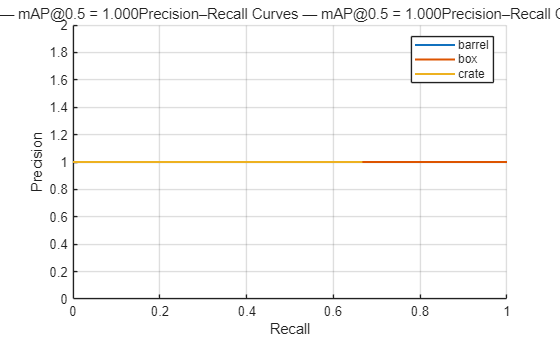


%% ┌────────────────────────────────────────────────────────┐
%% │ 6.  임의 이미지 시각화                                │
%% └────────────────────────────────────────────────────────┘
Itest = imread(tblTest.imageFilename{1});
% 추론
[bbox, score, label] = detect(detector, Itest, Threshold=0.3);

% 라벨+점수를 문자열로 변환
labelsAnnot = string(label) + ": " + string(round(score,2));

% 박스에 주석 달기

Ishow = insertObjectAnnotation(Itest, "rectangle", bbox, labelsAnnot);

figure; imshow(Ishow);
title("YOLOv4 Tiny — Inference Example");

save("detector_nao_0630.mat","detector");

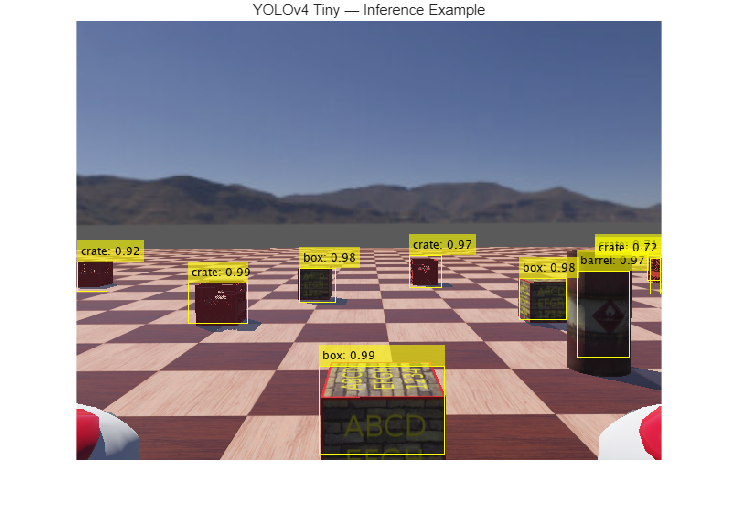

%% 1) dlnetwork 객체 꺼내기
% yolov4ObjectDetector → 네트워크 구조는 detector.Network 로 저장
net = detector.Network;

%% 2) 한눈에 구조 확인 ─ summary
disp("== YOLO 네트워크 요약 ==");
summary(net)                     % 층·파라미터·출력 크기 표 형태

%% 3) 그래프 형태 시각화 ─ plot
figure("Name","YOLOv4/Tiny Architecture","Units","normalized","Position",[0.1 0.1 0.8 0.8]);
plot(net);                       % dlnetwork 전용 시각화 (양방향 스크롤 가능)


% 🔎 팁: 레이어 이름이 겹쳐서 읽기 힘들면 노드 크기·글꼴 축소
%  -> figure 창에서 Toolbar > Layout > Fit to Window 를 눌러보세요.

%% 4) Deep Network Designer 로 열어서 탐색 (GUI)
%  - 블록별 파라미터, 연결 확인 & 수정 가능
deepNetworkDesigner(net);

%% 5) layerGraph 로 변환해 연결 테이블 보기 (원할 때만)
% lgraph = layerGraph(net);

== YOLO 네트워크 요약 ==


% figure; plot(lgraph);          % 표준 layerGraph 그림


   초기화됨: true

   학습 가능 파라미터 개수: 5.8M

   입력:
      1   'input_1'   416×416×3 영상



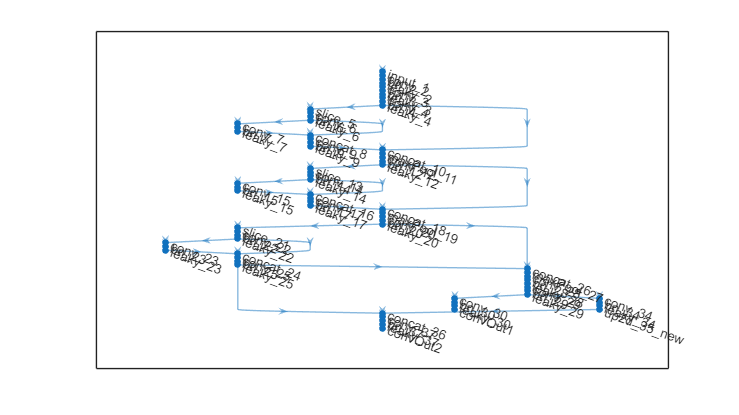

% =======================================================================
%                보조 함수들 (데이터 증강 / 클리닝 등)
% =======================================================================


function data = augmentData(A)
% 수평플립 + 랜덤 확대/축소 + HSV 지터
data = cell(size(A));
for ii = 1:size(A,1)
    I      = A{ii,1};
    bbox   = A{ii,2};
    labels = A{ii,3};

    % ▸ 색상 지터 (RGB 이미지에만)
    if size(I,3)==3
        I = jitterColorHSV(I, ...
            Contrast=0, Hue=0.1, Saturation=0.2, Brightness=0.2);
    end

    % ▸ 랜덤 수평 플립 & 스케일
    tform = randomAffine2d( ...
        XReflection=true, ...            % 좌우 반전
        Scale=[1 1.1]);                  % 최대 10 % 확대
    rout  = affineOutputView(size(I),tform,BoundsStyle="centerOutput");
    I     = imwarp(I,tform,OutputView=rout);

    [bbox,kept] = bboxwarp(bbox,tform,rout,OverlapThreshold=0.25);
    labels      = labels(kept);

    if isempty(kept)
        % 모든 박스가 사라지면 원본 사용
        data(ii,:) = A(ii,:);
    else
        data(ii,:) = {I,bbox,labels};
    end
end
end





function data = preprocessData(data,targetSize)
% Resize the images and scale the pixels to between 0 and 1. Also scale the
% corresponding bounding boxes.

for ii = 1:size(data,1)
    I = data{ii,1};
    imgSize = size(I);
    
    bboxes = data{ii,2};

    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);
    
    data(ii,1:2) = {I,bboxes};
end
end


function detector = downloadPretrainedYOLOv4Detector()
% Download a pretrained yolov4 detector.
if ~exist("yolov4TinyVehicleExample_24a.mat", "file")
    if ~exist("yolov4TinyVehicleExample_24a.zip", "file")
        disp("Downloading pretrained detector...");
        pretrainedURL = "https://ssd.mathworks.com/supportfiles/vision/data/yolov4TinyVehicleExample_24a.zip";
        websave("yolov4TinyVehicleExample_24a.zip", pretrainedURL);
    end
    unzip("yolov4TinyVehicleExample_24a.zip");
end
pretrained = load("yolov4TinyVehicleExample_24a.mat");
detector = pretrained.detector;
end

function tblOut = cleanBboxTable(tblIn,labelVar)
% - 잘못된 bbox(열<4, 비어 있음) 제거
% - 음수·0·NaN·Inf·소수 박스 제거/수정
% - 이미지 경계 밖 박스 클리핑
tblOut       = tblIn;                      % 복사본
rowsToDelete = false(height(tblIn),1);     % 삭제 플래그

for i = 1:height(tblIn)
    bbox = tblOut{i,labelVar}{1};          % {M×4 double} 또는 빈 행

    % ── 0) bbox 자체가 없거나 열 4개 미만 → 삭제
    if isempty(bbox) || size(bbox,2) < 4
        rowsToDelete(i) = true;
        continue
    end

    % ── 1) 이미지 크기 읽기
    I = imread(tblOut.imageFilename{i});
    [H,W,~] = size(I);

    % ── 2) 폭/높이>0, 유한값, 좌표≥1
    ok  = bbox(:,3)>0 & bbox(:,4)>0 & ...
          bbox(:,1)>=1 & bbox(:,2)>=1 & ...
          all(isfinite(bbox),2);
    bbox = bbox(ok,:);

    % 아무 것도 안 남으면 삭제
    if isempty(bbox)
        rowsToDelete(i) = true;
        continue
    end

    % ── 3) 절대값+정수화
    bbox = round(abs(bbox));

    % ── 4) 이미지 경계로 클리핑
    bbox(:,1) = min(bbox(:,1), W-1);
    bbox(:,2) = min(bbox(:,2), H-1);
    bbox(:,3) = min(bbox(:,3), W-bbox(:,1));
    bbox(:,4) = min(bbox(:,4), H-bbox(:,2));

    tblOut{i,labelVar}{1} = bbox;          % 수정 반영
end

% 빈 bbox 행 일괄 삭제
tblOut(rowsToDelete,:) = [];
end
